clear

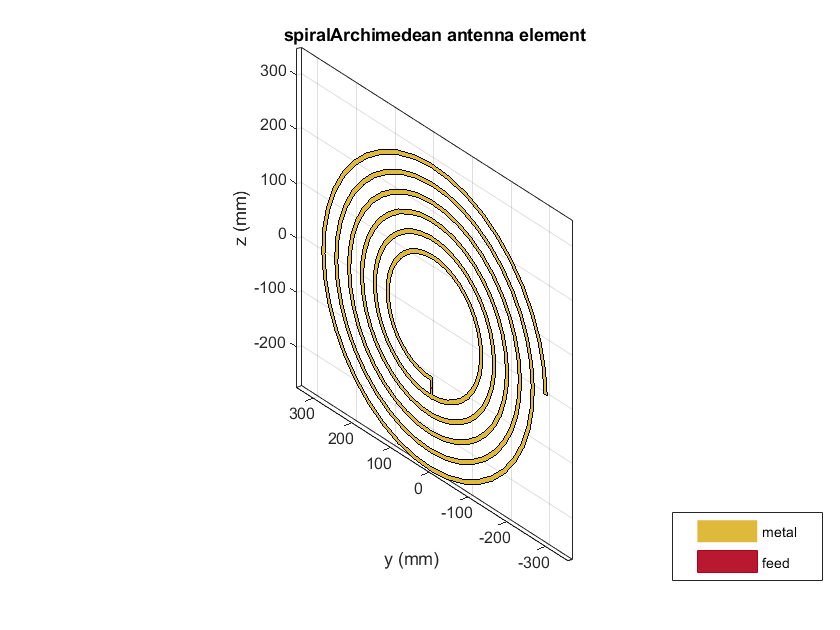

% Item 1
emi = spiralArchimedean('NumArms',1, 'Turns',6,'InnerRadius',0.1,'OuterRadius',0.3,'Tilt',90, 'TiltAxis', 'Y');
show(emi)

% Item 2
freq = linspace(14e6,16.5e6,150)

freq = 	1.0e+07 *

    1.4000    1.4017    1.4034    1.4050    1.4067    1.4084    1.4101    1.4117    1.4134    1.4151    1.4168    1.4185    1.4201    1.4218    1.4235    1.4252    1.4268    1.4285    1.4302    1.4319    1.4336    1.4352    1.4369    1.4386    1.4403    1.4419    1.4436    1.4453    1.4470    1.4487    1.4503    1.4520    1.4537    1.4554    1.4570    1.4587    1.4604    1.4621    1.4638    1.4654    1.4671    1.4688    1.4705    1.4721    1.4738    1.4755    1.4772    1.4789    1.4805    1.4822


imp = impedance(emi, freq)

imp = 	1.0e+03 *

   0.0000 + 0.0828i   0.0000 + 0.0833i   0.0000 + 0.0837i   0.0000 + 0.0842i   0.0000 + 0.0846i   0.0000 + 0.0851i   0.0000 + 0.0856i   0.0000 + 0.0861i   0.0000 + 0.0866i   0.0000 + 0.0871i   0.0000 + 0.0876i   0.0000 + 0.0881i   0.0000 + 0.0887i   0.0000 + 0.0893i   0.0000 + 0.0898i   0.0000 + 0.0904i   0.0000 + 0.0910i   0.0000 + 0.0917i   0.0000 + 0.0923i   0.0000 + 0.0930i   0.0000 + 0.0936i   0.0000 + 0.0943i   0.0000 + 0.0950i   0.0000 + 0.0958i   0.0000 + 0.0965i   0.0000 + 0.0973i   0.0000 + 0.0981i   0.0000 + 0.0989i   0.0000 + 0.0998i   0.0000 + 0.1007i   0.0000 + 0.1016i   0.0000 + 0.1025i   0.0000 + 0.1035i   0.0000 + 0.1045i   0.0000 + 0.1056i   0.0000 + 0.1066i   0.0000 + 0.1078i   0.0000 + 0.1089i   0.0000 + 0.1101i   0.0000 + 0.1114i   0.0000 + 0.1127i   0.0000 + 0.1141i   0.0000 + 0.1155i   0.0000 + 0.1170i   0.0001 + 0.1186i   0.0001 + 0.1202i   0.0001 + 0.1219i   0.0001 + 0.1237i   0.0001 + 0.1256i   0.0001 + 0.1276i


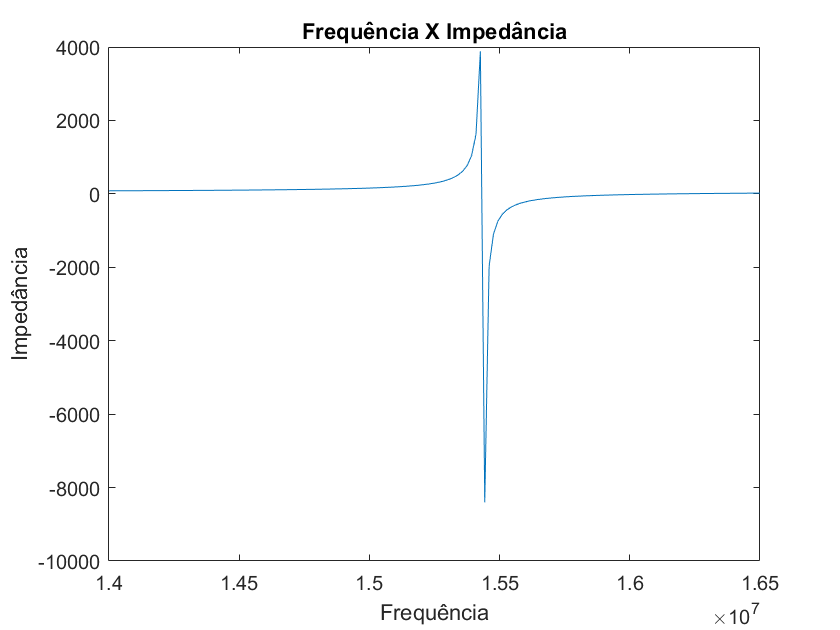

plot(freq, imag(imp))
title("Frequência X Impedância")
xlabel('Frequência');
ylabel('Impedância');

fc = freq(imag(imp) == max(imag(imp)));

imag(impedance(emi,1.616785*1e7))

ans = -5.4545e-04

fr = 1.616785*1e7

fr = 16167850

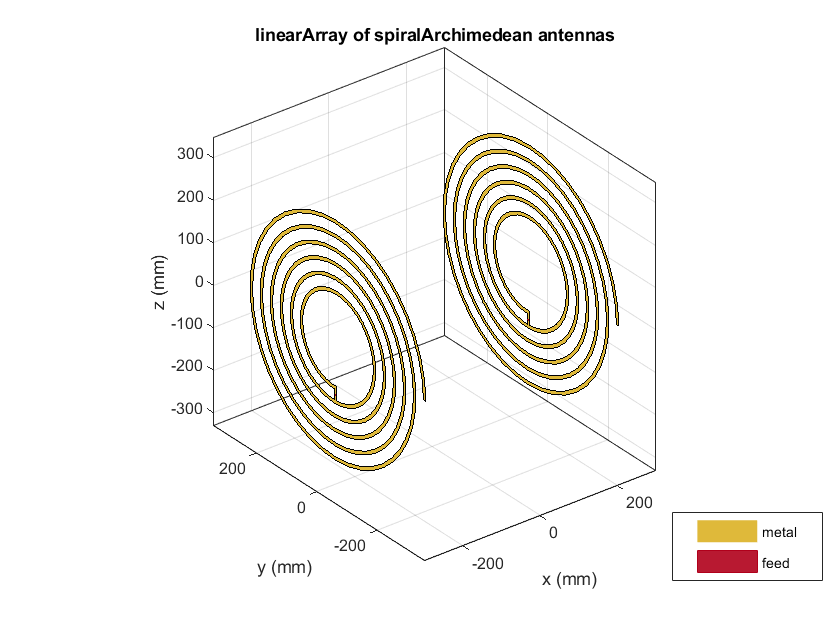

% Item 3
rec = spiralArchimedean('NumArms',1, 'Turns',6,'InnerRadius',0.1,'OuterRadius',0.3,'Tilt',90, 'TiltAxis', 'Y');
array = linearArray('Element',[emi rec],'ElementSpacing',0.5);
show(array)

% Item 4
ganhos=sparameters(array,freq);

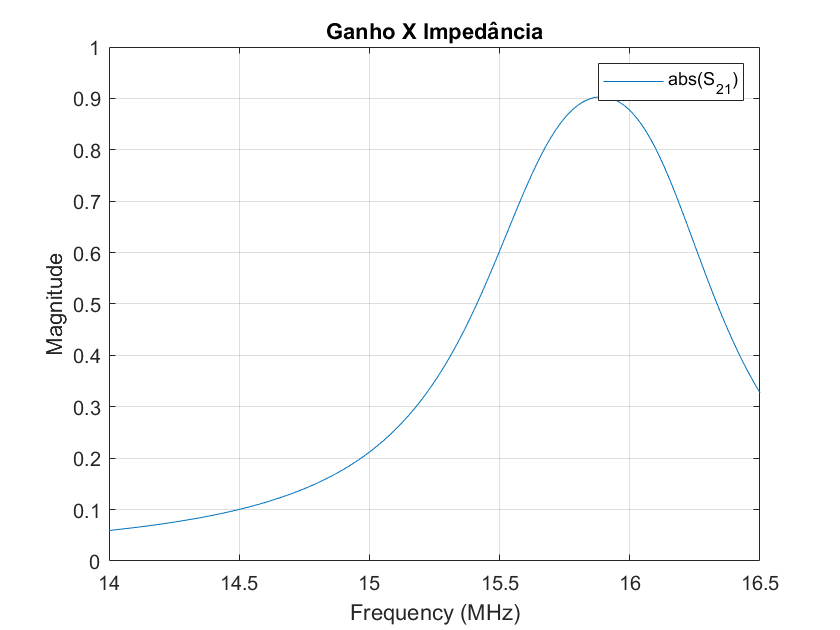

% Item 5
rfplot(ganhos,2,1,'abs')
title("Ganho X Impedância")

% Item 6
x=zeros(10,150);
d=linspace(0.1,1,10);
for n=1:1:10
   array=linearArray('ElementSpacing',d(1,n));
   %array.ElementSpacing = d(1,n);
   ganhos=sparameters(array,linspace(10e6,10e7,150));
   x(n,:)=abs(rfparam(ganhos,2,1));
end

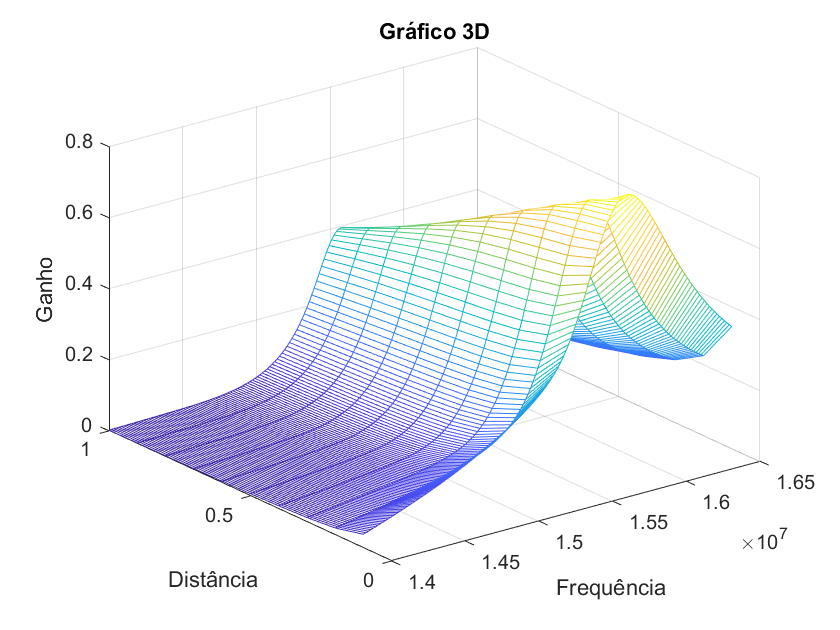

mesh(freq, d, x)
title('Gráfico 3D')
xlabel('Frequência')
ylabel('Distância')
zlabel('Ganho')

% Item 8 (Ganho)
sigma = 20

sigma = 20

Wc = fc

Wc = 1.5426e+07

L = sigma/Wc

L = 1.2965e-06

C = 1/(sigma*Wc)

C = 3.2412e-09

impedancia = zeros(length(freq), 1)

impedancia =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



for g = 1:length(freq)
    impedancia(g) = 1i * freq(g) * L * 1/(1i * freq(g) * C)/((1i * freq(g) * L)+(1/(1i * freq(g) * C))) + 10 * 1i * freq(g) * L;
end

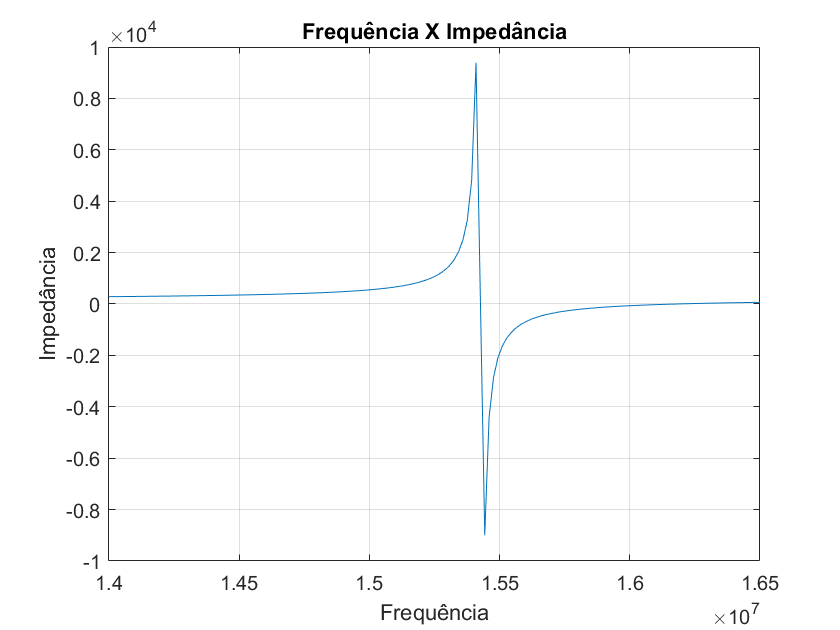

plot(freq, imag(impedancia))
grid()
title("Frequência X Impedância")
xlabel('Frequência');
ylabel('Impedância');

% Item 8 (M)
M1 = 1/Wc;
Rc = 1;

% Ganho X M
M2 = linspace(M1, 0.1*1e-7, 150);
G2 = zeros(length(M2), 1);

for g = 1:length(M2)
    G = (abs(1j * Wc * M2(g))/Rc).^2;
    G2(g,1) = G;
end

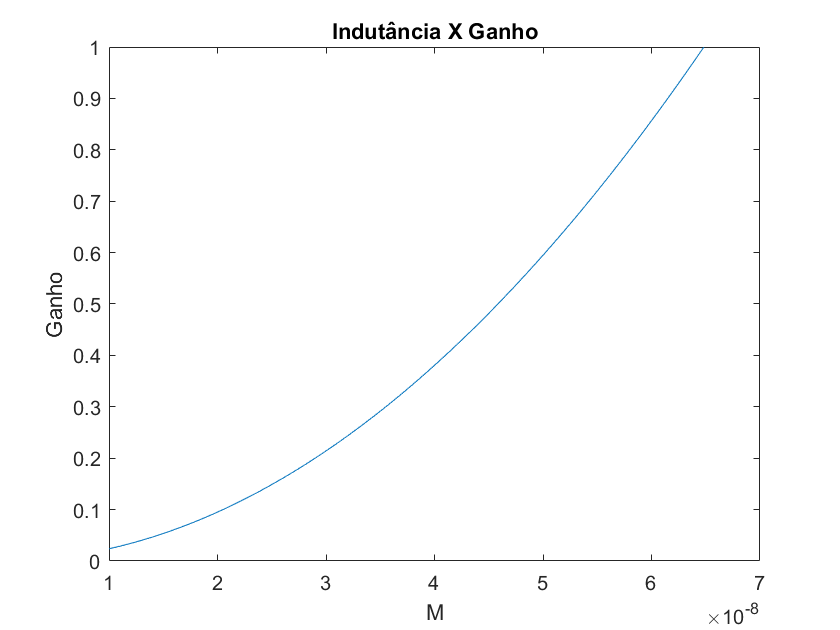

plot(M2, G2);
title("Indutância X Ganho")
xlabel('M');
ylabel('Ganho');

% Ganho X Distância

D2 = linspace(0.1, 1, 150);

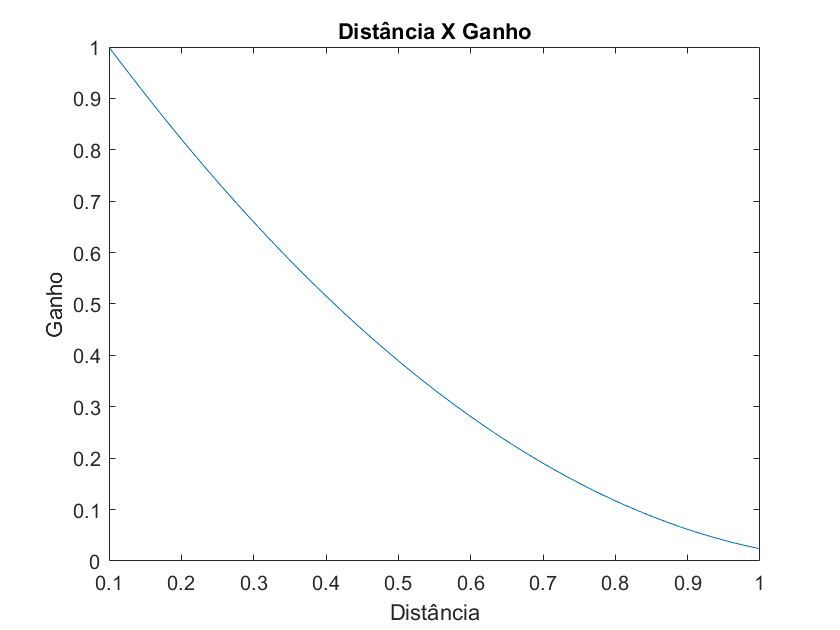

plot(D2, G2);
title("Distância X Ganho")
xlabel('Distância');
ylabel('Ganho');